COLOR = struct(...
'BLUE', [0 0.4470 0.7410], ...
'ORANGE', [0.8500 0.3250 0.0980], ...
'YELLOW', [0.9290 0.6940 0.1250], ...
'PURPLE', [0.4940 0.1840 0.5560], ...
'GREEN', [0.4660 0.6740 0.1880], ...
'LIGHT_BLUE', [0.3010 0.7450 0.9330], ...
'RED', [0.6350 0.0780 0.1840] ...
);

## Generate ideal sensor values

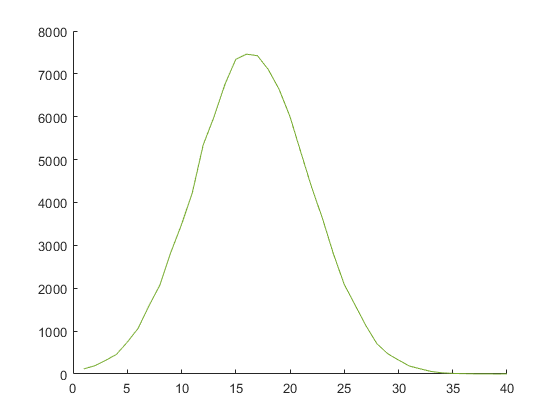

N=10e4;
d=floor([16*normrnd(0,1,[1 N])/3+16]);%, 16*normrnd(0,1,[1 N])/3+3*16]);
d(d>64) = [];
d(d<0) = [];
[a_orig,b] = hist(d,unique(d));
x = 1:size(a_orig,2);
a = a_orig;

figure
hold on
plot(x,a,'Color',COLOR.GREEN);

## Add defects

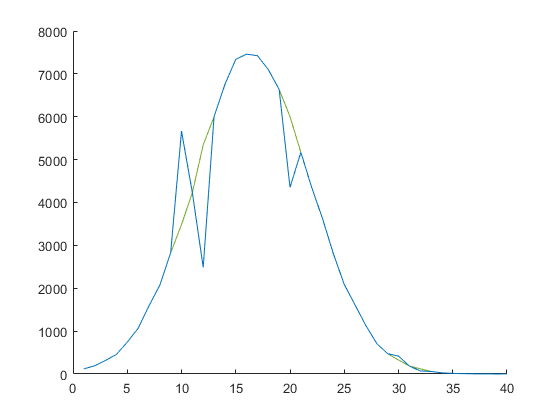

N_osh = 3;
osh = randi(size(a,2),1,N_osh);
N_ush = 3;
ush = randi(size(a,2),1,N_ush);

% osh = 18:25;
% ush = [];

effective_defects = containers.Map('KeyType','double','ValueType','char');
for i = 1:size(osh,2)
    strength = 1.5+.25*2*(rand-.5);
    a(osh(i)) = a(osh(i))*strength;
    effective_defects(osh(i)) = ['Overshoot'];%  ' num2str(round(100*(strength-1))) '%'];
end
for i = 1:size(ush,2)
    strength = .5+.25*2*(rand-.5);
    a(ush(i)) = a(ush(i))*strength;
    effective_defects(ush(i)) = ['Undershoot'];% ' num2str(round(100*(1-strength))) '%'];
end

a_defect = a;
plot(x,a_defect,'Color',COLOR.BLUE);

## Filter

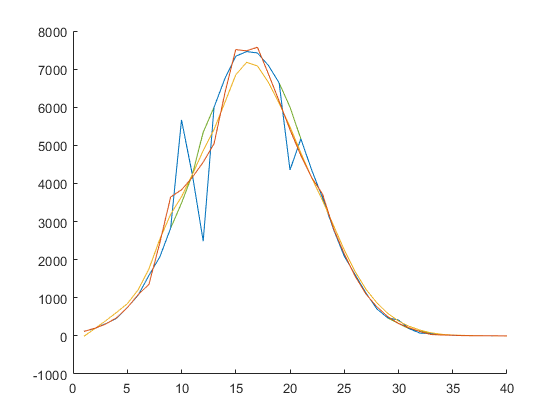

% alpha = .5;
% af = [a(1)];
% 
% for i = 2:size(a,2)
%     af(i) = af(i-1) + alpha * (a(i) - af(i-1));
% end
% 
% plot(x,af,'Color',COLOR.ORANGE);
yy2 = smooth(a_defect,0.2,'lowess');
yy = smooth(a_defect,7,'sgolay',3);
plot(x,yy2,'Color',COLOR.YELLOW);
plot(x,yy,'Color',COLOR.ORANGE);

## Outlier

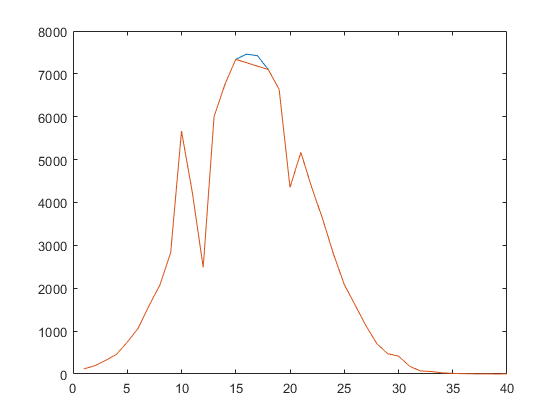

a_fill_pchip = filloutliers(a_defect,'pchip');
a_fill_linear = filloutliers(a_defect,'linear');
a_fill_spline = filloutliers(a_defect,'spline');

figure
plot(x,a_defect,x,a_fill_linear)

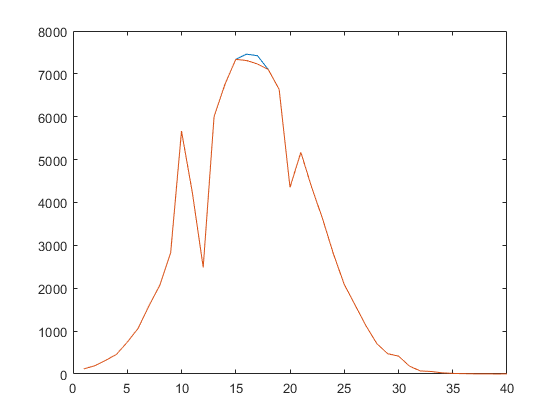

figure
plot(x,a_defect,x,a_fill_pchip)

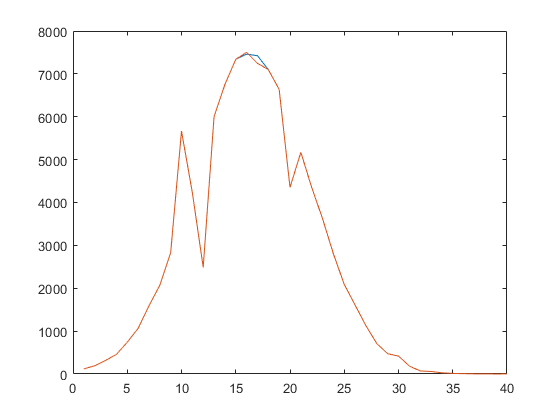

figure
plot(x,a_defect,x,a_fill_spline)